## 系统建模 Plant

% m mass                1.0 kg
% k spring constant     20.0 N/m
% b damping constant    10.0 Ns/m
% F input force         1.0 N

m = 1;
k = 20;
b = 10;
F = 1;

s = tf('s');
P = 1/(m*s^2+b*s+k);
set(P,'InputName','Force','OutputName','x');
P

P =
 
  从输入 "Force" 到输出 "x":
         1
  ---------------
  s^2 + 10 s + 20
 
连续时间传递函数。
模型属性


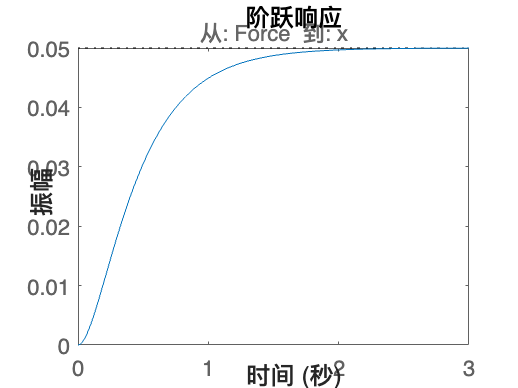

step(P)

% linearSystemAnalyzer('step',P)

% 稳态值   0.05
% 稳态误差 0.95
% 上升时间 0.884s (10%~90%)
% 调节时间 1.59s
% 超调    /

## 控制器设计 Controllor

% 定义PID控制器
% 初始化控制器参数
Kp = 1;
Ki = 1;
Kd = 1;
E_0 = 0;

s =tf('s');
C1 = Kp + Ki/s + Kd*s + Kd*E_0

C1 =
 
  s^2 + s + 1
  -----------
       s
 
连续时间传递函数。
模型属性


C2 = pid(Kp,Ki,Kd);
tf(C2) % 验证两种控制器的生成方法

ans =
 
  s^2 + s + 1
  -----------
       s
 
连续时间传递函数。
模型属性


% 定义比例控制器
Kp = 300;
Ki = 0;
Kd = 0;
E_0 = 0;
C = Kp + Ki/s + Kd*s + Kd*E_0

C =
 
  300
 
静态增益。
模型属性


% 串联Controllor&Plant
G = series(C,P);
% 闭环系统
sys = feedback(G,1,-1)

sys =
 
  从输入到输出 "x":
        300
  ----------------
  s^2 + 10 s + 320
 
连续时间传递函数。
模型属性


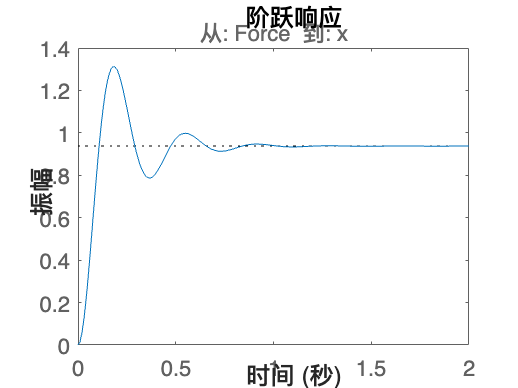

set(sys,'InputName','Force','OutputName','x');
t = 0:0.01:2;
step(sys,t)

% linearSystemAnalyzer('step',sys)

% 稳态值   0.938
% 稳态误差 0.062
% 响应峰值 1.31
% 上升时间 0.0727s (10%~90%)
% 峰值时间 0.184s
% 调节时间 0.772s
% 超调    40.1%

% 比例控制器效果
% 优点：降低了上升时间和稳态误差，减少了调节时间
% 缺点：增加了超调量

% 定义比例微分控制器
Kp = 300;
Ki = 0;
Kd = 10;
E_0 = 0;
C = Kp + Ki/s + Kd*s + Kd*E_0

C =
 
  10 s + 300
 
连续时间传递函数。
模型属性


% 串联Controllor&Plant
G = series(C,P);
% 闭环系统
sys = feedback(G,1,-1)

sys =
 
  从输入到输出 "x":
     10 s + 300
  ----------------
  s^2 + 20 s + 320
 
连续时间传递函数。
模型属性


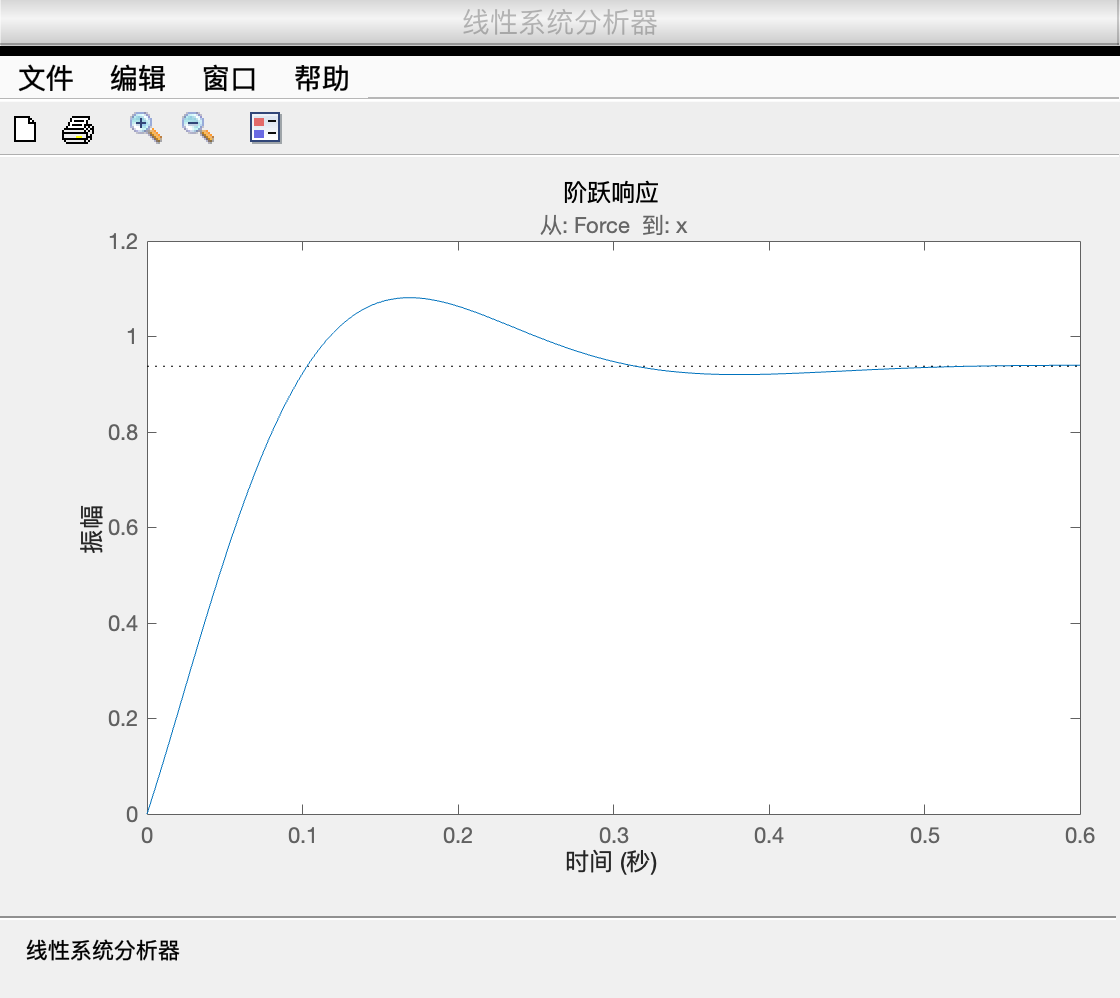

set(sys,'InputName','Force','OutputName','x');
t = 0:0.01:2;
% step(sys,t)
linearSystemAnalyzer('step',sys)


% 稳态值   0.938
% 稳态误差 0.062
% 响应峰值 1.08
% 上升时间 0.0777s (10%~90%)
% 峰值时间 0.17s
% 调节时间 0.29s
% 超调    15.3%

% 比例微分控制器效果(VS比例控制器)
% 优点：显著降低超调量和调节时间
% 缺点：小幅增加上升时间

% 定义比例积分控制器
Kp = 30;
Ki = 70;
Kd = 0;
E_0 = 0;
C = Kp + Ki/s + Kd*s + Kd*E_0

C =
 
  30 s + 70
  ---------
      s
 
连续时间传递函数。
模型属性


% 串联Controllor&Plant
G = series(C,P);
% 闭环系统
sys = feedback(G,1,-1)

sys =
 
  从输入到输出 "x":
         30 s + 70
  ------------------------
  s^3 + 10 s^2 + 50 s + 70
 
连续时间传递函数。
模型属性


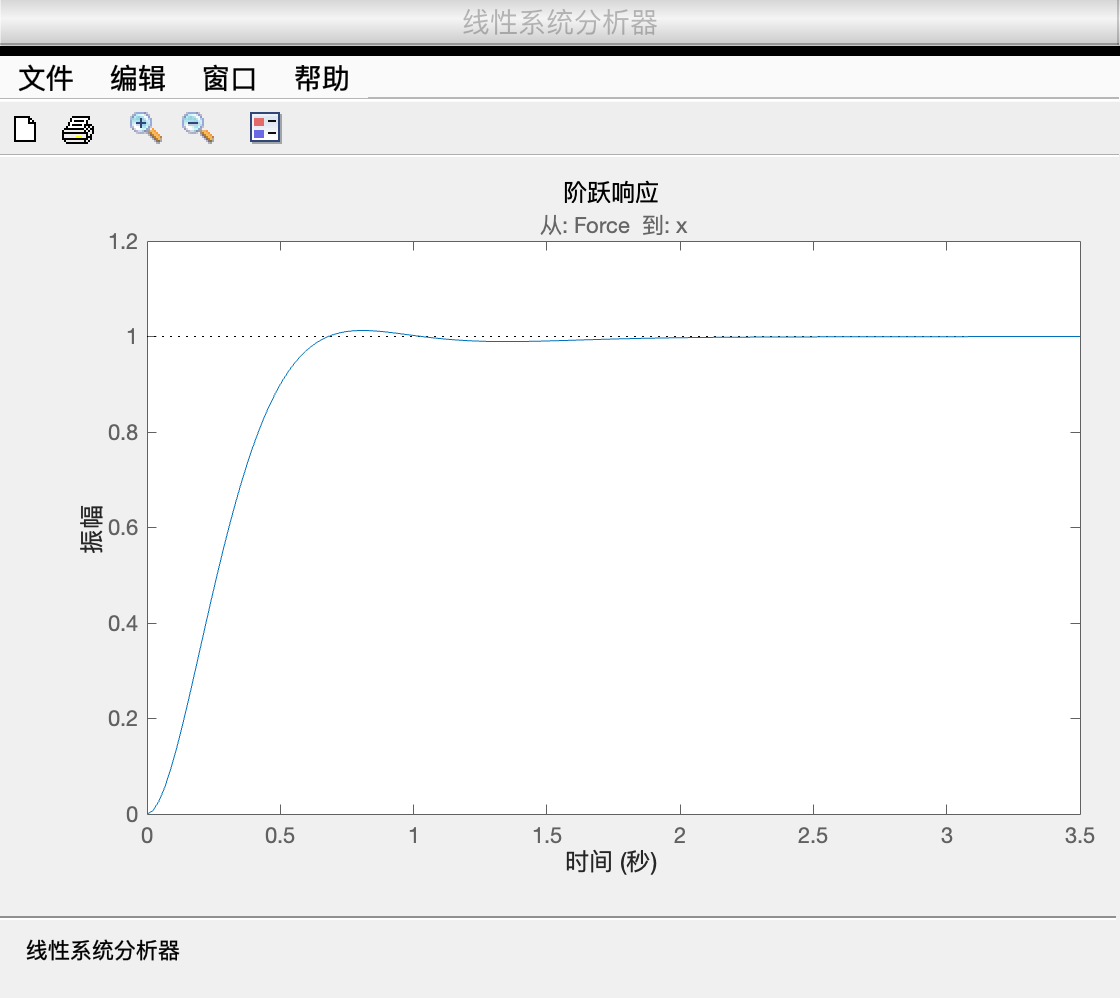

set(sys,'InputName','Force','OutputName','x');
t = 0:0.01:2;
% step(sys,t)
linearSystemAnalyzer('step',sys)


% 稳态值   1
% 稳态误差 0
% 响应峰值 1.01
% 上升时间 0.408s (10%~90%)
% 峰值时间 0.618s
% 调节时间 0.814s
% 超调    1.26%

% 比例积分控制器效果(VS比例控制器)
% 优点：显著减小稳态误差(完全跟踪)和超调量
% 缺点：增加了上升时间和调节时间

% 定义比例积分微分控制器
Kp = 350;
Ki = 300;
Kd = 50;
E_0 = 0;
C = Kp + Ki/s + Kd*s + Kd*E_0

C =
 
  50 s^2 + 350 s + 300
  --------------------
           s
 
连续时间传递函数。
模型属性


% 串联Controllor&Plant
G = series(C,P);
% 闭环系统
sys = feedback(G,1,-1)

sys =
 
  从输入到输出 "x":
     50 s^2 + 350 s + 300
  --------------------------
  s^3 + 60 s^2 + 370 s + 300
 
连续时间传递函数。
模型属性


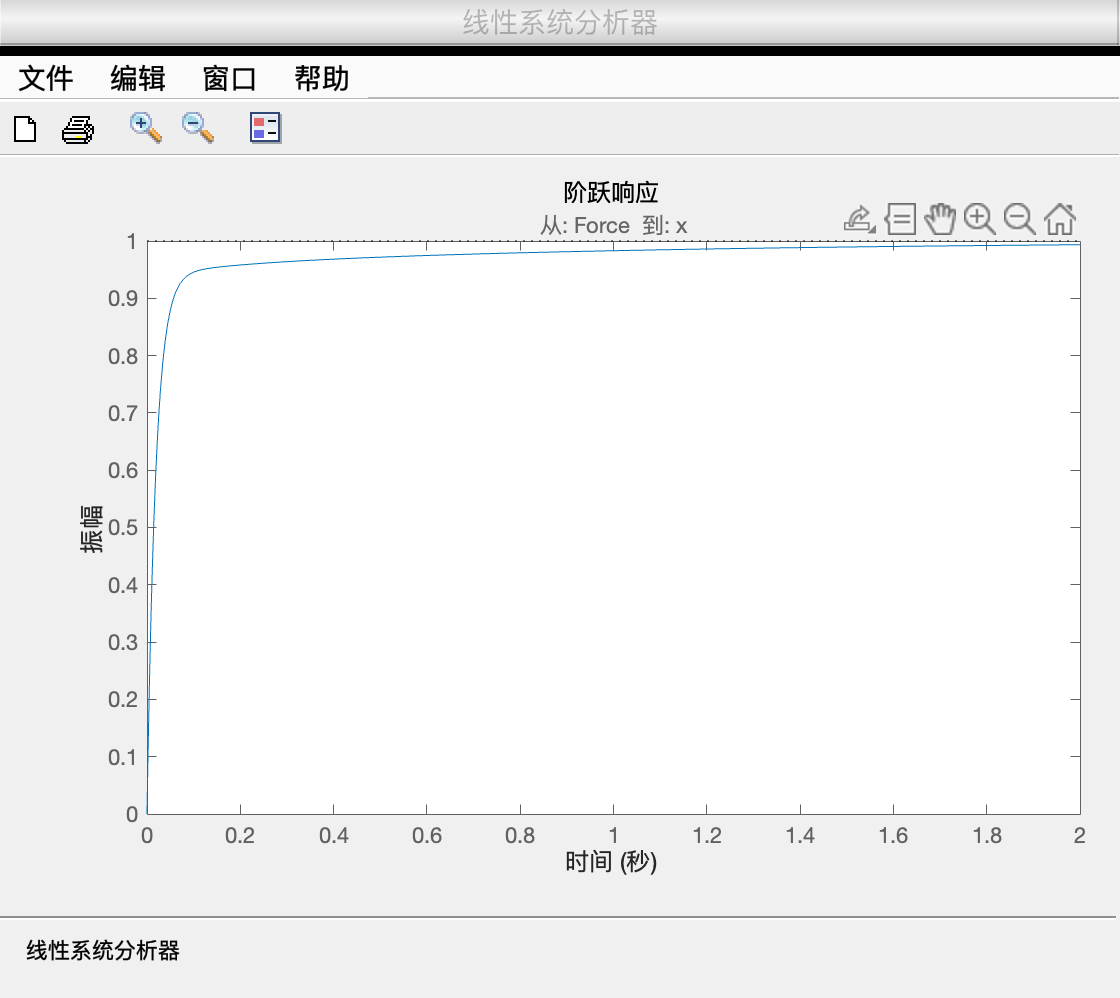

set(sys,'InputName','Force','OutputName','x');
t = 0:0.01:2;
% step(sys,t)
linearSystemAnalyzer('step',sys)


% 稳态值   1
% 稳态误差 0
% 响应峰值 1
% 上升时间 0.0548s (10%~90%)
% 峰值时间 /
% 调节时间 0.831s
% 超调    /

% 比例积分微分控制器效果(VS比例控制器)
% 优点：稳态误差和超调量均为0，大大加快上升时间
% 缺点：小幅增加调节时间

## 结果对比

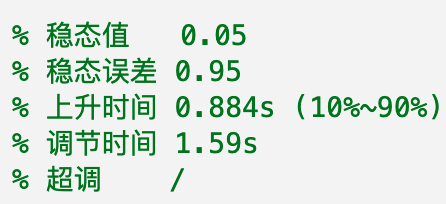

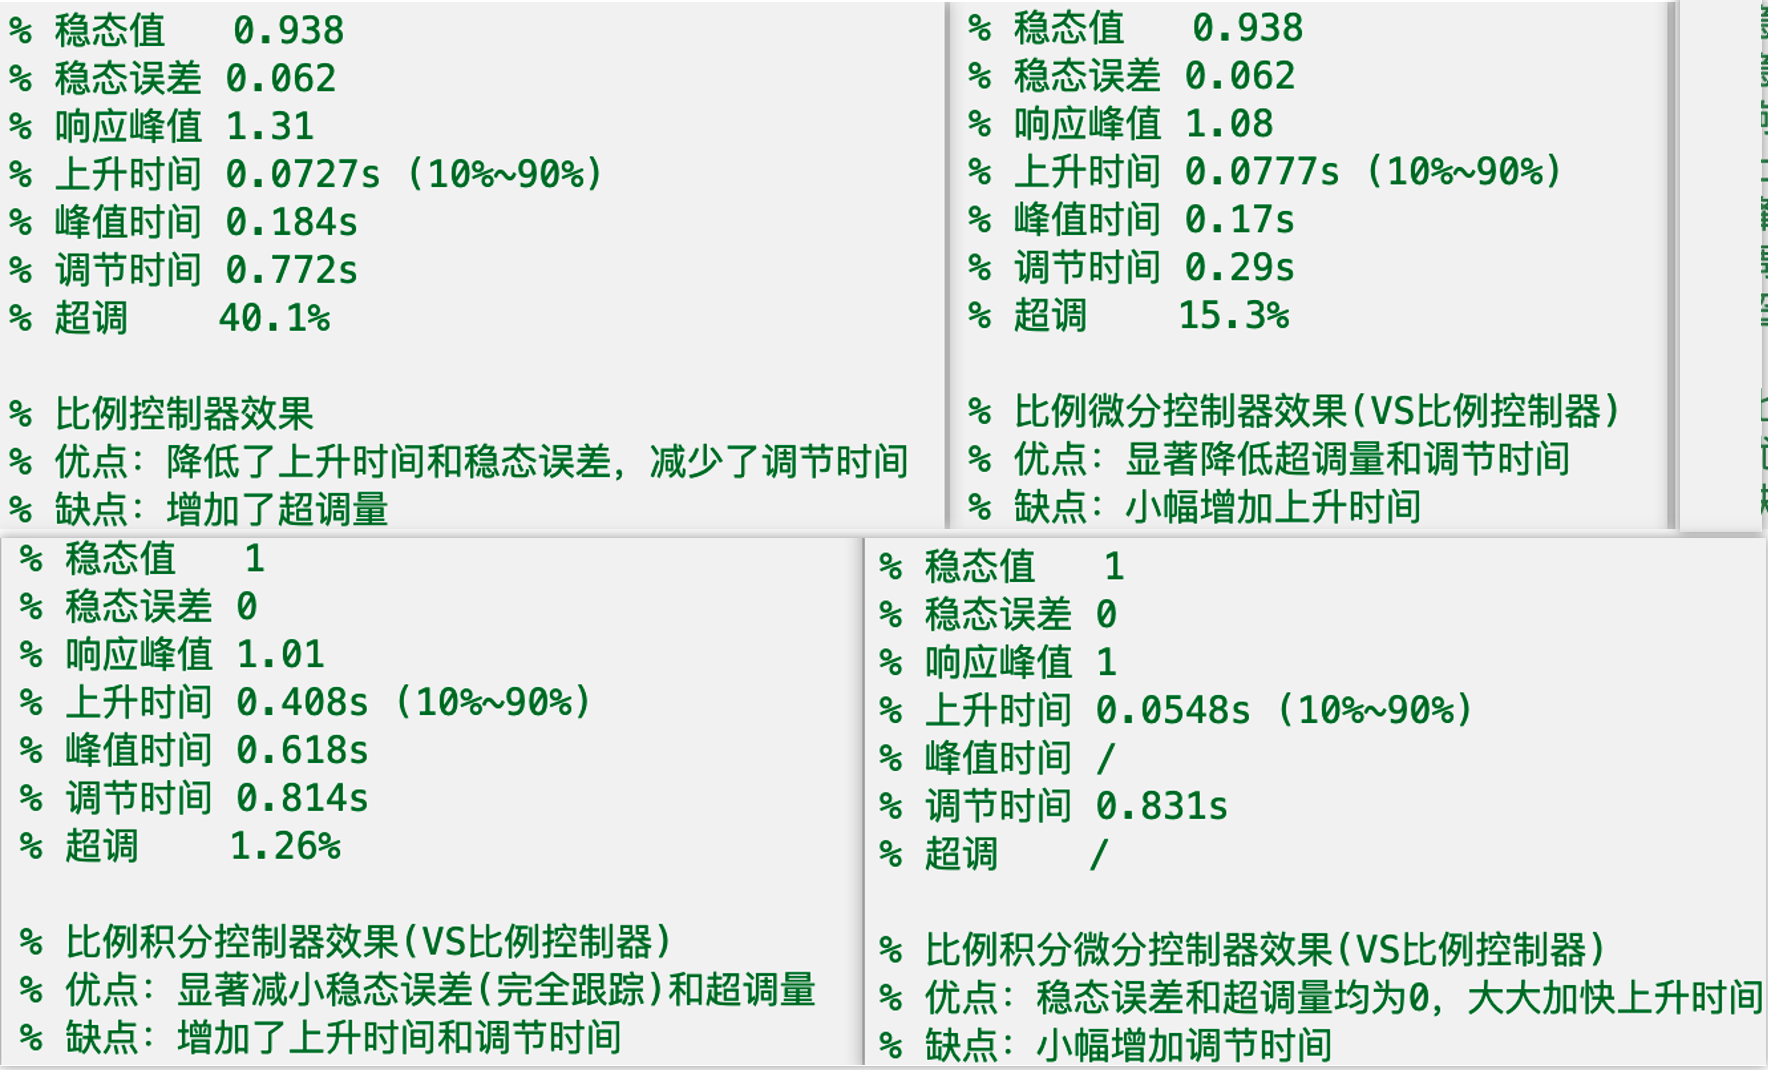

## PID Tuning

% pidTuner(P,'p')
opts = pidtuneOptions('CrossoverFrequency',32,'PhaseMargin',90);
[C3 , info] = pidtune(P,'pid',opts)

C3 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  且 Kp = 320, Ki = 796, Kd = 32.2
 
并联型的连续时间 PID 控制器。
模型属性


info = 包含以下字段的 struct :
                Stable: 1
    CrossoverFrequency: 32
           PhaseMargin: 90



% 串联Controllor&Plant
G = series(C3,P);
% 闭环系统
sys = feedback(G,1,-1)

sys =
 
  从输入到输出 "x":
     32.15 s^2 + 320 s + 796.2
  -------------------------------
  s^3 + 42.15 s^2 + 340 s + 796.2
 
连续时间传递函数。
模型属性


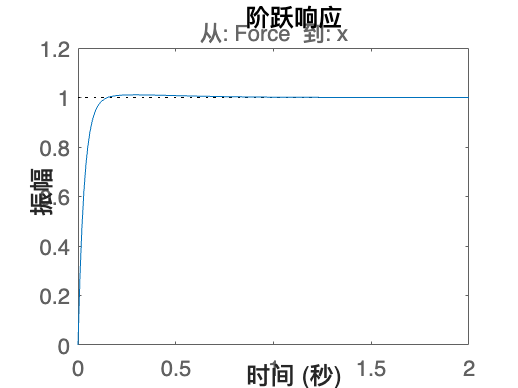

set(sys,'InputName','Force','OutputName','x');
t = 0:0.01:2;
step(sys,t)